 

startPos = 
         0         0         1     1.674
        -1         0         0         0
         0        -1         0   -0.1895
         0         0         0         1


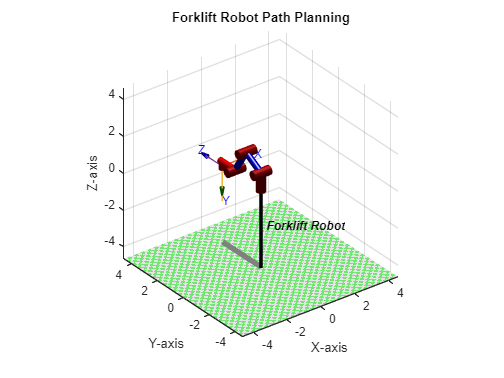

% Forklift Robot Path Planning Script
% This script defines the robot arm for our forklift with manipulator project
% using Denavit-Hartenberg (DH) parameters. It simulates a sequence of movements
% to pick up and move a pallet using mtraj and ctraj functions for trajectory generation.

clear; clc; close all; % Clear the workspace and close any open figures


% Define the robot using DH parameters (4 DOF)
% Each Link represents a joint with its parameters: [theta d a alpha]
% Note: These parameters are specific to the design and kinematics of the forklift robot.
armLink(1) = Link([0 0.5 0 pi/2]); % Joint 1: length 0.5, twist angle pi/2
armLink(2) = Link([0 0 1.3 0 0]); % Joint 2: length 1.3
armLink(3) = Link([0 0 1.6 0]); % Joint 3: length 1.6
armLink(4) = Link([0 0 0 0]); % Joint 4: This is a simple prismatic joint, with no offset

% Create the robot model and set the tool frame
% The tool frame represents the end-effector (the forks) of the robot.
forkliftRobot = SerialLink(armLink, 'name', 'Forklift Robot');
forkliftRobot.tool = [0, 0, 1, 1; 0, -1, 0, -0.25; 1, 0, 0, 0; 0, 0, 0, 1]; % Tool frame transformation matrix
forkliftRobot.name = 'Forklift Robot';

% Define specific poses for the robot to move through
% These are the different positions the forklift will move to during the pallet manipulation.
% SE3 represents 3D translation and rotation.
restPose = [0 7/20*pi -5/6*pi 29/60*pi]; % Resting pose with forks at the base
initialPosition = forkliftRobot.fkine(restPose); % Calculate Cartesian position from restPose
turningPosition = SE3(2, 0, 1.75)*SE3.Rx(-pi/2); % Position to prepare for turning (tilting the arm)
turningPositionFront = SE3(2, 0, 1.75)*SE3.Rx(-pi/2); % Alternate position for turning preparation
palletApproachPosition = SE3(0, 1.5, 1.75)*SE3.Rx(-pi/2); % Position to approach the pallet
palletPickUpPosition = SE3(0, 2.5, 1.8)*SE3.Rx(-pi/2); % Position to grab the pallet
palletLiftedPosition = SE3(0, 2.5, 2)*SE3.Rx(-pi/2); % Position after lifting the pallet
palletMovePosition = SE3(0, 1.5, 2)*SE3.Rx(-pi/2); % Position to move the lifted pallet
prePalletPlacementPosition = SE3(2.5, 0, 0.5) * SE3.Rx(-pi/2); % Position before placing the pallet
palletPlacementRotationPosition = SE3(0,2.5,0.5) * SE3.Rx(-pi/2); % Rotation before placing the pallet
palletDropPosition = SE3(0,3,-0.5) * SE3.Rx(-pi/2); % Position for dropping the pallet

% Time vector for the movements, from 0 to 1 second with small steps (0.01 seconds)
% This defines the granularity of the movement in time for smooth transitions.
timeVector = [0:0.01:1];

% Cartesian trajectory planning between specified poses
% ctraj creates a series of Cartesian positions between start and end poses for smooth movements
trajectory1 = ctraj(turningPositionFront, turningPosition, length(timeVector)/2); % Path for turning from front to position
trajectory3 = ctraj(palletApproachPosition, palletPickUpPosition, length(timeVector)/2); % Path to pick up pallet
trajectory5 = ctraj(palletLiftedPosition, palletMovePosition, length(timeVector)/2); % Path to move lifted pallet
trajectory7 = ctraj(turningPosition, turningPositionFront, length(timeVector)/2); % Return path to original turning position
trajectory9 = ctraj(initialPosition, prePalletPlacementPosition, length(timeVector)/2); % Path before placing pallet
trajectory11 = ctraj(prePalletPlacementPosition, palletPlacementRotationPosition, length(timeVector)/2); % Rotation path
trajectory13 = ctraj(palletPlacementRotationPosition, palletDropPosition, length(timeVector)/2); % Final drop path

% Solve joint angles for the planned Cartesian paths using inverse kinematics
% Using inverse kinematics to find joint configurations (q) for the Cartesian paths
jointAngles1 = forkliftRobot.ikine(trajectory1, 'mask', [1 1 1 1 0 0]); % Solve for joint angles during first trajectory
jointAngles3 = forkliftRobot.ikine(trajectory3, 'mask', [1 1 1 1 0 0]); % Solve for joint angles during second trajectory
jointAngles5 = forkliftRobot.ikine(trajectory5, 'mask', [1 1 1 1 0 0]); % Solve for joint angles during third trajectory
jointAngles7 = forkliftRobot.ikine(trajectory7, 'mask', [1 1 1 1 0 0]); % Solve for joint angles during fourth trajectory
jointAngles9 = forkliftRobot.ikine(trajectory9, 'mask', [1 1 1 1 0 0]); % Solve for joint angles during fifth trajectory
jointAngles11 = forkliftRobot.ikine(trajectory11, 'mask', [1 1 1 1 0 0]); % Solve for joint angles during sixth trajectory
jointAngles13 = forkliftRobot.ikine(trajectory13, 'mask', [1 1 1 1 0 0]); % Solve for joint angles during seventh trajectory

% Trajectory planning in joint space
% mtraj generates smooth joint-space movements between specified configurations
% using a polynomial interpolation for smooth transitions.
jointTrajectory0 = mtraj(@tpoly, restPose, jointAngles1(1,:), timeVector); % Smooth movement from restPose to jointAngles1
jointTrajectory2 = mtraj(@tpoly, jointAngles1(end,:), jointAngles3(1,:), timeVector); % Smooth movement to jointAngles3
jointTrajectory4 = mtraj(@tpoly, jointAngles3(end,:), jointAngles5(1,:), timeVector); % Smooth movement to jointAngles5
jointTrajectory6 = mtraj(@tpoly, jointAngles5(end,:), jointAngles7(1,:), timeVector); % Smooth movement to jointAngles7
jointTrajectory8 = mtraj(@tpoly, jointAngles7(end,:), restPose, timeVector); % Return movement from jointAngles7 to restPose
jointTrajectory10 = mtraj(@tpoly, jointTrajectory8(end,:), jointAngles9(1,:), timeVector); % Movement to pre-pallet placement position
jointTrajectory12 = mtraj(@tpoly, jointAngles11(end,:), jointAngles13(1,:), timeVector); % Movement for final pallet drop

% Plot the robot's movements for visualization
% Using the plot function to animate the robot and visualize each step of the movement.
figure;
forkliftRobot.plot(jointTrajectory0,'fps', 50); % Plot first trajectory
forkliftRobot.plot(jointAngles1,'fps', 50); % Plot second trajectory
forkliftRobot.plot(jointTrajectory2,'fps', 50); % Plot third trajectory
forkliftRobot.plot(jointAngles3,'fps', 50); % Plot fourth trajectory
forkliftRobot.plot(jointTrajectory4,'fps', 50); % Plot fifth trajectory
forkliftRobot.plot(jointAngles5,'fps', 50); % Plot sixth trajectory
forkliftRobot.plot(jointTrajectory6,'fps', 50); % Plot seventh trajectory
forkliftRobot.plot(jointAngles7,'fps', 50); % Plot eighth trajectory
forkliftRobot.plot(jointTrajectory8,'fps', 50); % Plot return trajectory
forkliftRobot.plot(jointTrajectory10, 'fps', 50); % Smooth transition to rotated pose
forkliftRobot.plot(jointAngles9, 'fps', 50);  % Plot final movement to rotated pose
forkliftRobot.plot(jointAngles11, 'fps', 50); % Plot joint angles during rotation
forkliftRobot.plot(jointTrajectory12, 'fps', 50); % Plot final movement to drop pallet
forkliftRobot.plot(jointAngles13, 'fps', 50); % Plot final joint angles during pallet drop

% Add title and axis labels for better understanding
title('Forklift Robot Path Planning'); % Title of the plot
xlabel('X-axis'); % Label for X-axis
ylabel('Y-axis'); % Label for Y-axis
zlabel('Z-axis'); % Label for Z-axis
grid on; % Enable grid on the plot for clarity
